clearvars;
load("idealECG.mat");

**Weiner filtering (on stationary signal)**

*Part 1*

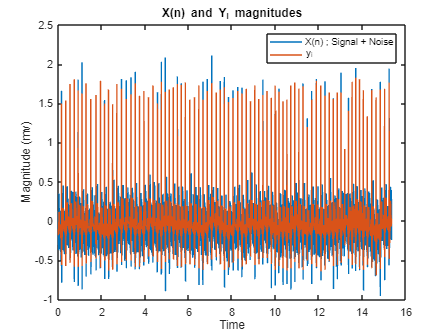

y_i = idealECG;
fs = 500;
T = 1/fs; 
f1 = 50;

num_points = size(y_i, 2);
time_axis = linspace(0, T * (num_points-1), num_points);  %time axis from the frequency

n_wg = awgn(y_i,10,'measured'); %white gaussian noise
n_50 = 0.2*sin(2*pi*f1*time_axis);  %50 Hz noise

x_n = n_wg + n_50;   %input signal

figure;
plot(time_axis,x_n);
hold on;
plot(time_axis,y_i);
xlabel('Time');
ylabel('Magnitude (mv)');
legend('X(n) ; Signal + Noise','y_i');
title("X(n) and Y_i magnitudes");

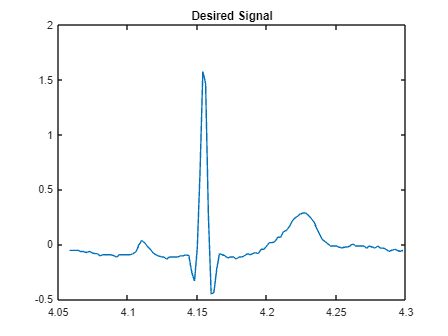

start_n = 2030;
end_n = 2150;
desired_time = time_axis(start_n:end_n);
desired_y_i = y_i(start_n:end_n);

figure;
% plot(time_axis,y_i)
% hold on;
plot(desired_time,desired_y_i);
title("Desired Signal");

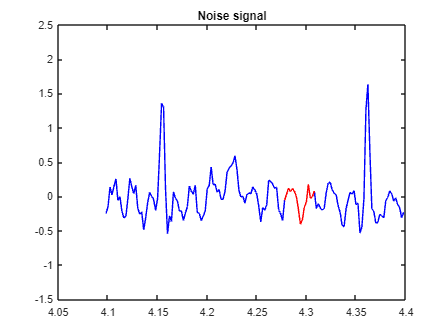

noise_time = time_axis(2140:2155);
noise_signal = x_n(2140:2155);

figure;
plot(time_axis(2050:2200),x_n(2050:2200),'b');
hold on;
plot(noise_time,noise_signal,'r');
title("Noise signal");
ylim([-1.5,2.5]);

order = randi([1,min(length(noise_signal),length(desired_y_i))],1,1);

w0 = wienerWeights(order,desired_y_i,noise_signal);

y_hat = [];
for i = start_n:end_n
    x = transpose(x_n(i-order+1:i));
    % y = transpose(w0).*x;
    % size(y)
    y = dot(w0,x);
    y_hat = [y_hat y];
end

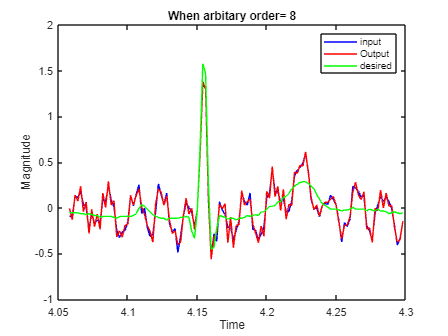

figure;
plot(desired_time,x_n(start_n:end_n),'b');
hold on;
plot(desired_time,y_hat,'r');
hold on;
plot(desired_time,desired_y_i,'g')
xlabel("Time");
ylabel("Magnitude");
title(sprintf('When arbitary order= %d',order))
legend("input",'Output','desired');

minimum_error = inf;
optimum_order = 1;
optimum_w0 = zeros(order,1);
orders = [];
errors = [];
optimum_y_hat = [];

for order = 1:min(length(noise_signal),length(desired_y_i)) 
    w0 = wienerWeights(order,desired_y_i,noise_signal);
    y_hat = [];
    for i = start_n:end_n
        x = transpose(x_n(i-order+1:i));
        y = dot(w0,x);
        y_hat = [y_hat y];
    end

    error = mean((desired_y_i-y_hat).^2);

    if error < minimum_error
        minimum_error = error;
        optimum_order = order;
        optimum_w0 = w0;
        optimum_y_hat = y_hat;
    end

    errors = [errors error];
    orders = [orders order];

end

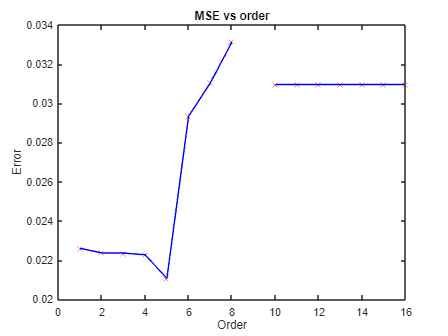

figure;
plot(orders,errors, 'xr');
hold on;
plot(orders,errors, '-b');
xlabel('Order');
ylabel('Error');
title("MSE vs order");

fprintf('Optimum filter order = %d, error at the optimum filter order = %.4f\n', optimum_order, minimum_error);

Optimum filter order = 5, error at the optimum filter order = 0.0211


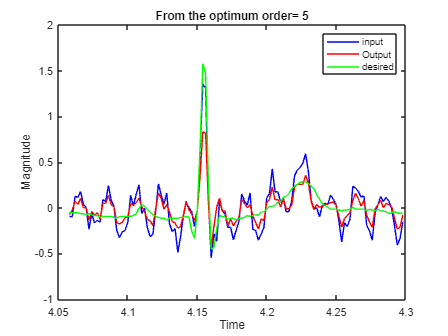

figure;
plot(desired_time,x_n(start_n:end_n),'b');
hold on;
plot(desired_time,optimum_y_hat,'r');
hold on;
plot(desired_time,desired_y_i,'g')
xlabel("Time");
ylabel("Magnitude");
title(sprintf('From the optimum order= %d',optimum_order))
legend("input",'Output','desired');

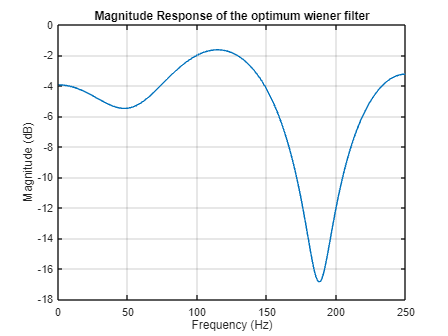

[H, w] = freqz(optimum_w0, 1, 1024, fs);
mag_dB = 20 * log10(abs(H));

figure;
plot(w, mag_dB);
title('Magnitude Response of the optimum wiener filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

Initializing Window Designer....

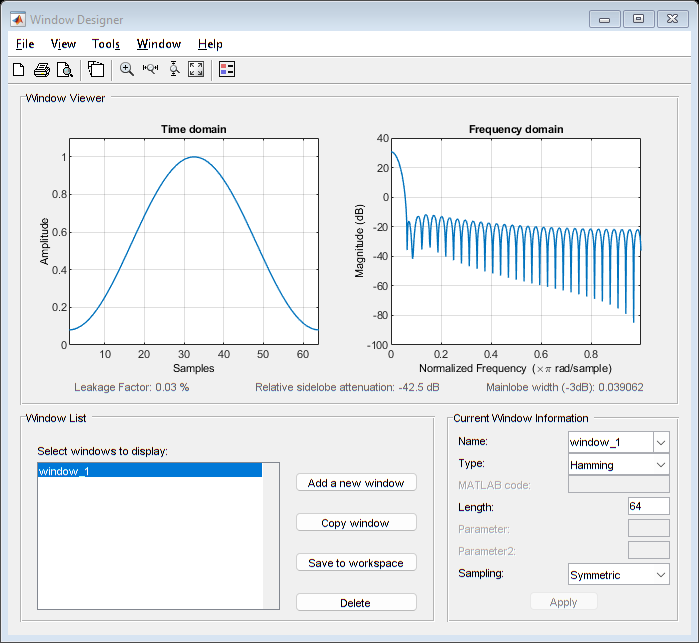

. done. 


nfft = num_points;
[pxx_yi,f_yi] = periodogram(y_i,window,nfft,fs);

Initializing Window Designer....

. done. 


[pxx_x,f_x] = periodogram(x_n,window,nfft,fs);

Initializing Window Designer....

. done. 


yi_output = zeros();
for i = order:size(y_i,2)
     x = transpose(x_n(i-optimum_order+1:i));
     y = transpose(optimum_w0).*x;
     y = dot(optimum_w0,x);
     yi_output = [yi_output y];
end

[pxx_yi_output,f_yi_output] = periodogram(yi_output,window,nfft,fs);

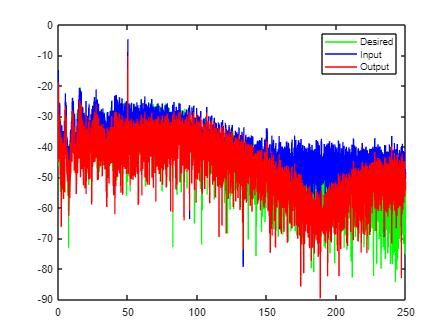


figure;
plot(f_yi, 10*log10(pxx_yi),'g'); 
hold on;
plot(f_x, 10*log10(pxx_x),'b'); 
hold on;
plot(f_yi_output, 10*log10(pxx_yi_output),'r');
legend("Desired","Input","Output");

Part 2

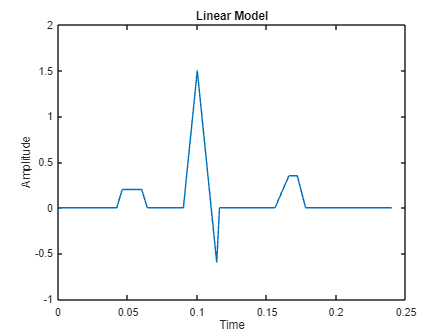

linearModel = [];
len = size(desired_y_i,2);  %here len = 121, Therefore the rest 

for i = 1:len
    if (22<=i && i<25)
        linearModel = [linearModel 0.1*(i-22)];
    elseif (25<=i && i< 31)
        linearModel = [linearModel 0.2];
    elseif (31<=i && i< 34)
        linearModel = [linearModel 0.1*(33-i)];
    elseif (46<=i && i< 52)
        linearModel = [linearModel 0.3*(i-46)];
    elseif (52<=i && i< 59)
        linearModel = [linearModel 0.3*(56-i)];
    elseif (80<=i && i<85)
        linearModel = [linearModel 0.07*(i-79)];
    elseif (84<=i && i< 87)
        linearModel = [linearModel 0.35];
    elseif (87<=i && i< 90)
        linearModel = [linearModel (7/60)*(90-i)];
    else 
        linearModel = [linearModel 0];
    end
end


time_linearModel = linspace(0, T * (len-1), len);
figure;
plot(time_linearModel,linearModel);
ylim([-1 2]);
xlabel("Time");
ylabel("Amplitude");
title("Linear Model")

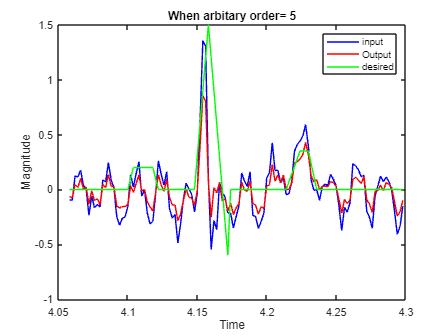

order = randi([1,min(length(noise_signal),length(linearModel))],1,1);

w0 = wienerWeights(order,linearModel,noise_signal);

y_hat = [];
for i = start_n:end_n
    x = transpose(x_n(i-order+1:i));
    % y = transpose(w0).*x;
    % size(y)
    y = dot(w0,x);
    y_hat = [y_hat y];
end

figure;
plot(desired_time,x_n(start_n:end_n),'b');
hold on;

plot(desired_time,y_hat,'r');
hold on;
plot(desired_time,linearModel,'g')
xlabel("Time");
ylabel("Magnitude");
title(sprintf('When arbitary order= %d',order))
legend("input",'Output','desired');

minimum_error = inf;
optimum_order = 1;
optimum_w0 = zeros(order,1);
orders = [];
errors = [];
optimum_y_hat = [];

for order = 1:min(length(noise_signal),length(linearModel)) 
    w0 = wienerWeights(order,linearModel,noise_signal);
    y_hat = [];
    for i = start_n:end_n
        x = transpose(x_n(i-order+1:i));
        y = dot(w0,x);
        y_hat = [y_hat y];
    end

    error = mean((linearModel-y_hat).^2);

    if error < minimum_error
        minimum_error = error;
        optimum_order = order;
        optimum_w0 = w0;
        optimum_y_hat = y_hat;
    end

    errors = [errors error];
    orders = [orders order];

end

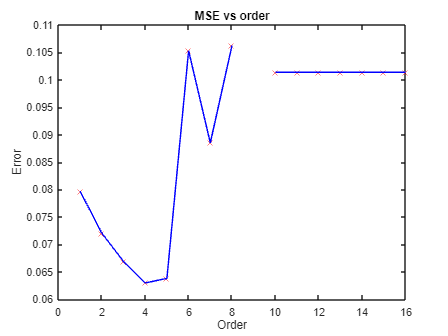

figure;
plot(orders,errors, 'xr');
hold on;
plot(orders,errors, '-b');
xlabel('Order');
ylabel('Error');
title("MSE vs order");

fprintf('Optimum filter order = %d, error at the optimum filter order = %.4f\n', optimum_order, minimum_error);

Optimum filter order = 4, error at the optimum filter order = 0.0630


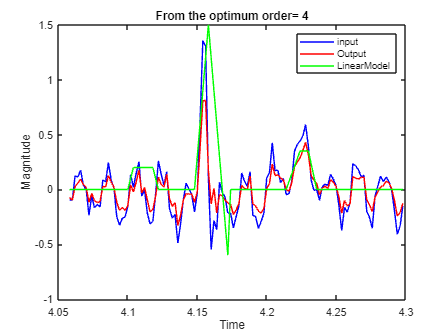

figure;
plot(desired_time,x_n(start_n:end_n),'b');
hold on;
plot(desired_time,optimum_y_hat,'r');
hold on;
plot(desired_time,linearModel,'g')
xlabel("Time");
ylabel("Magnitude");
title(sprintf('From the optimum order= %d',optimum_order))
legend("input",'Output','LinearModel');

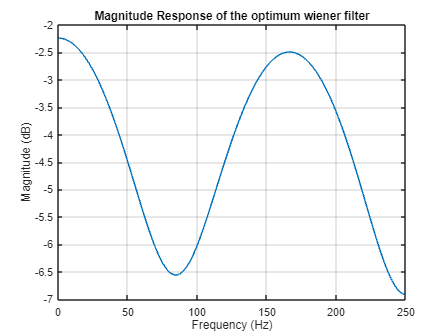

[H, w] = freqz(optimum_w0, 1, 1024, fs);
mag_dB = 20 * log10(abs(H));

figure;
plot(w, mag_dB);
title('Magnitude Response of the optimum wiener filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

Initializing Window Designer....

. done. 


yi_output = zeros();
for i = order:size(y_i,2)
     x = transpose(x_n(i-optimum_order+1:i));
     y = transpose(optimum_w0).*x;
     y = dot(optimum_w0,x);
     yi_output = [yi_output y];
end
[pxx_yi_output,f_yi_output] = periodogram(yi_output,window,nfft,fs);

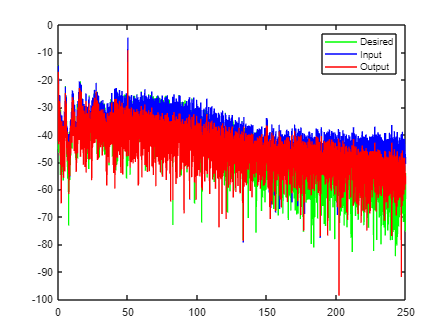


figure;
plot(f_yi, 10*log10(pxx_yi),'g'); 
hold on;
plot(f_x, 10*log10(pxx_x),'b'); 
hold on;
plot(f_yi_output, 10*log10(pxx_yi_output),'r');
legend("Desired","Input","Output");